clear all
close all
clc

% defining the System
alpha = pi/6;
beta =0.8;
gamma = pi/3;

A = [cos(alpha) sin(alpha); -sin(alpha) cos(alpha)]*beta;
B = [0.5; 0.5];

% defining the constraints
% for the states
F = [cos(gamma) sin(gamma); -cos(gamma) -sin(gamma); sin(gamma) -cos(gamma); -sin(gamma) cos(gamma)];
f = [2;1;2;5];
% for the input
M = [1; -1];
m = [0.5;0.5];
X = Polyhedron(F, f);

MOSEK Version 10.1.12 (Build date: 2023-9-20 10:51:32)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86



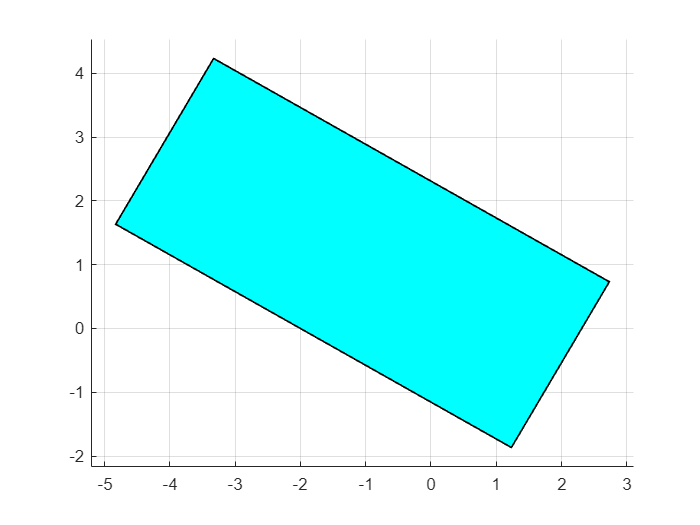

plot(X,'color', 'c')

**Computing the Controlled Invariant Set**

Omega(1) = X;
for k = 2:100
    G = [Omega(k-1).A*A Omega(k-1).A*B;zeros(size(M,1),size(F*A,2)) M];
    g = [Omega(k-1).b; m];
    Constraints = Polyhedron(G, g);
    preset = projection(Constraints, 1:2);
    Omega(k) = intersect(preset, Omega(k-1));
    if Omega(k) == Omega(k-1)
        disp(['Invariant set found:']);
        CInf = Omega(k)
        break
    end
end

Invariant set found:


Polyhedron in R^2 with representations:
    H-rep (irredundant) : Inequalities   8 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


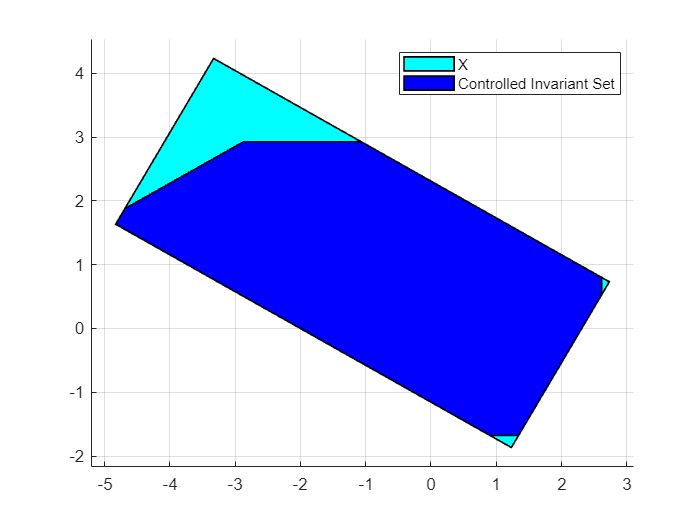

plot(X,'color', 'c', CInf,'color', 'b')
legend('X', 'Controlled Invariant Set')

**LQR Controller**

Q = eye(2);
R = 1;
[K,S,e] = dlqr(A,B,Q,R)

K =     0.2365    0.5038


S =     2.2796   -0.0659
   -0.0659    1.6078


e =    0.5078 + 0.2688i
   0.5078 - 0.2688i


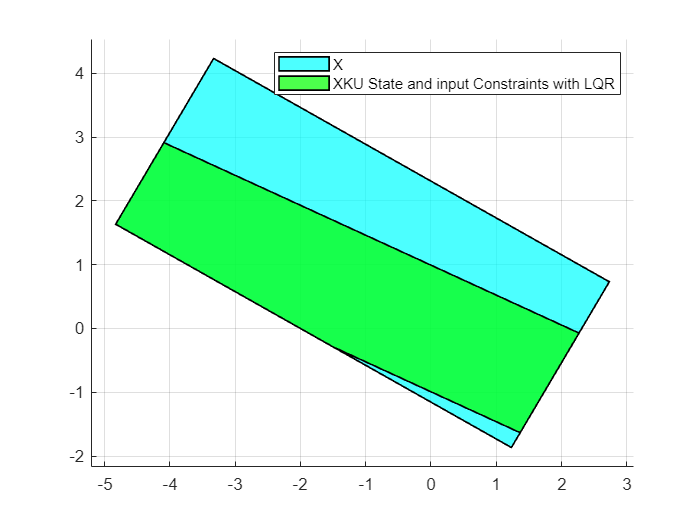

K = -K;
U = Polyhedron([F;M*K], [f;m]);
plot(X,'alpha', 0.7,'color', 'c', U,'alpha', 0.7, 'color', 'g')
legend('X', 'XKU State and input Constraints with LQR')


Acl = A +B*K;
% Compute the invariance set of the controlled system
Omega(1) = U;
for k = 2:100
    preset = Polyhedron(Omega(k-1).A*Acl, Omega(k-1).b);
    Omega(k) = intersect(preset, Omega(k-1));
    if Omega(k) == Omega(k-1)
        disp(['Invariant set found:']);
        OmegaInf = Omega(k)
        break
    end
end

Invariant set found:


Polyhedron in R^2 with representations:
    H-rep (irredundant) : Inequalities   7 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


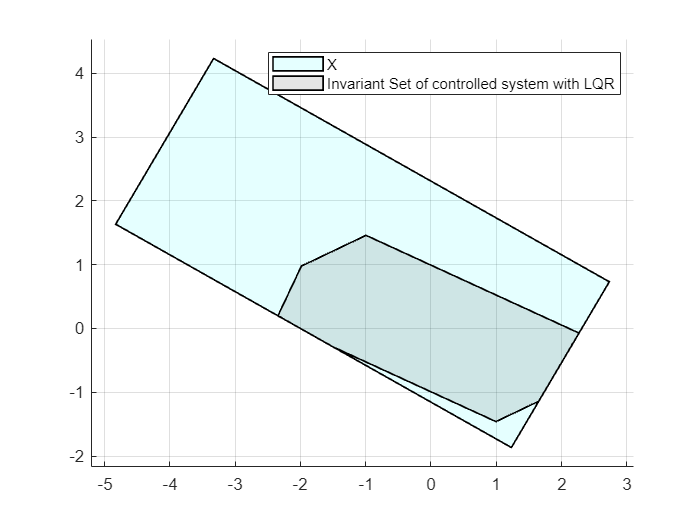

plot(X,'alpha', 0.1, 'color','c', OmegaInf,'color', 'k','alpha', 0.1)
legend('X', 'Invariant Set of controlled system with LQR')

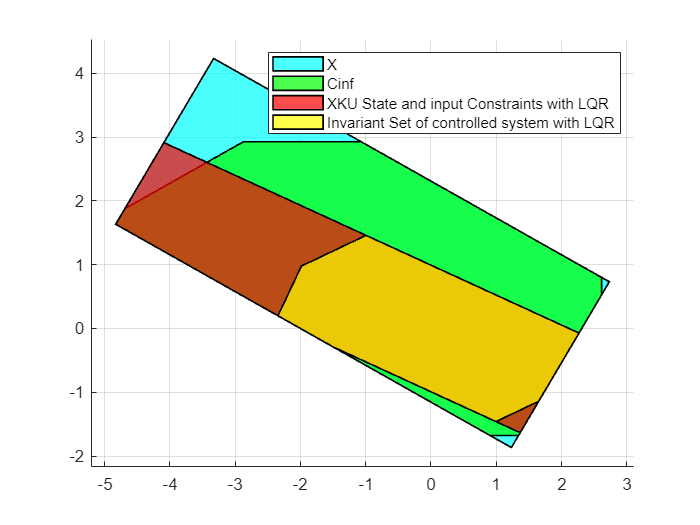


plot(X,'alpha', 0.7,'color', 'c', CInf,'alpha', 0.7,'color', 'g', U,'alpha', 0.7, 'color', 'r', OmegaInf,'alpha', 0.7,'color', 'y')
legend('X', 'Cinf','XKU State and input Constraints with LQR', 'Invariant Set of controlled system with LQR')